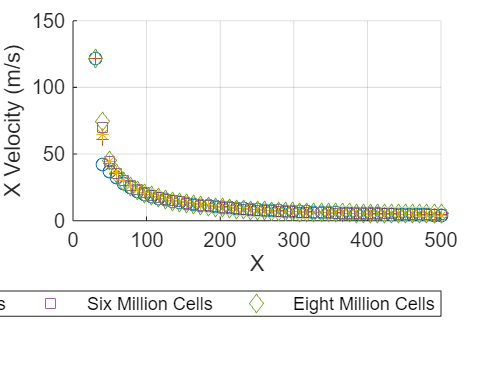

% This MATLAB script was created to fulfill the thesis requirements of Keith Sequeira (Msc Computational Fluid Dynamics, IRP -2024),, titled "Establishing Best Practices for Modeling Jet Blast."
% This MATLAB code was made with assistance from ChatGPT and Bing AI

% Define the folder where you want to save the plots
saveFolder = 'C:\Users\keith\Desktop\Cranfield University\Tamas Jozsa - Keith\Simulations\Single_Jet\Pictures\MI';

% Ensure the folder exists
if ~exist(saveFolder, 'dir')
    mkdir(saveFolder);
end

% Plot xvelocity data and save
figure('Position', [100, 100, 850, 650]); % Set figure size
hold on;
legend_entries_xvelocity = {'One Million Cells', 'Two Million Cells', 'Four Million Cells', 'Six Million Cells', 'Eight Million Cells'};
for i = 1:5
    if ~isempty(xvelocity_data{i})
        plot(xvelocity_data{i}(:,1), xvelocity_data{i}(:,2), 'LineStyle', 'none', 'Marker', markerStyles{i}, 'DisplayName', legend_entries_xvelocity{i});
    else
        disp(['xvelocity data not loaded: ', xvelocity_files{i}]);
    end
end
xlabel('X');
ylabel('X Velocity (m/s)');
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
grid on;
hold off;
saveas(gcf, fullfile(saveFolder, 'MeshIndependence_XVelocity.jpeg')); % Save plot

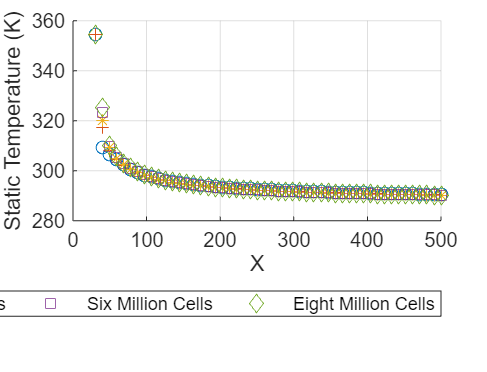


% Plot stemperature data and save
figure('Position', [100, 100, 850, 650]); % Set figure size
hold on;
legend_entries_stemperature = {'One Million Cells', 'Two Million Cells', 'Four Million Cells', 'Six Million Cells', 'Eight Million Cells'};
for i = 1:5
    if ~isempty(stemperature_data{i})
        plot(stemperature_data{i}(:,1), stemperature_data{i}(:,2), 'LineStyle', 'none', 'Marker', markerStyles{i}, 'DisplayName', legend_entries_stemperature{i});
    else
        disp(['stemperature data not loaded: ', stemperature_files{i}]);
    end
end
xlabel('X');
ylabel('Static Temperature (K)');
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
grid on;
hold off;
saveas(gcf, fullfile(saveFolder, 'MeshIndependence_StaticTemperature.jpeg')); % Save plot

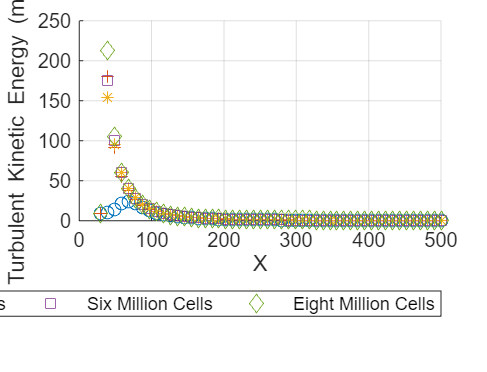


% Plot turbulent kinetic energy data and save
figure('Position', [100, 100, 850, 650]); % Set figure size
hold on;
legend_entries_tke = {'One Million Cells', 'Two Million Cells', 'Four Million Cells', 'Six Million Cells', 'Eight Million Cells'};
for i = 1:5
    if ~isempty(tke_data{i})
        plot(tke_data{i}(:,1), tke_data{i}(:,2), 'LineStyle', 'none', 'Marker', markerStyles{i}, 'DisplayName', legend_entries_tke{i});
    else
        disp(['TKE data not loaded: ', tke_files{i}]);
    end
end
xlabel('X');
ylabel('Turbulent Kinetic Energy (m^2/s^2)');
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
grid on;
hold off;
saveas(gcf, fullfile(saveFolder, 'MeshIndependence_tke.jpeg')); % Save plot


% Mesh Independence Study
mesh_sizes = [1e6, 2e6, 4e6, 6e6, 8e6]; % Example mesh sizes

% Initialize arrays to store average metrics
avg_xvelocity = zeros(1, 5);
avg_stemperature = zeros(1, 5);
avg_tke = zeros(1, 5);

% Calculate average metrics for each dataset
for i = 1:5
    if ~isempty(xvelocity_data{i})
        avg_xvelocity(i) = mean(xvelocity_data{i}(:,2));
    end
    if ~isempty(stemperature_data{i})
        avg_stemperature(i) = mean(stemperature_data{i}(:,2));
    end
    if ~isempty(tke_data{i})
        avg_tke(i) = mean(tke_data{i}(:,2));
    end
end

% Print average values in the terminal
disp('Average X Velocities (m/s):');

Average X Velocities (m/s):


disp(avg_xvelocity);

   13.3488   14.2828   11.9812   12.1324   14.3783




disp('Average Static Temperatures (K):');

Average Static Temperatures (K):


disp(avg_stemperature);

  295.1854  295.1133  293.9540  294.1466  295.4178




disp('Average Turbulent Kinetic Energies (m^2/s^2):');

Average Turbulent Kinetic Energies (m^2/s^2):


disp(avg_tke);

    3.8583   10.2465   10.1134   10.5969   11.4191



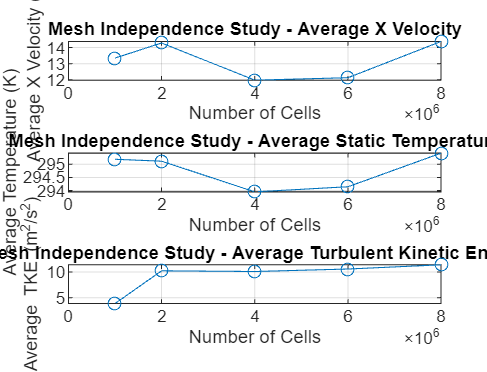


% Plot Mesh Independence Results and save
figure('Position', [100, 100, 850, 650]); % Set figure size
subplot(3,1,1);
plot(mesh_sizes, avg_xvelocity, '-o');
title('Mesh Independence Study - Average X Velocity');
xlabel('Number of Cells');
ylabel('Average X Velocity (m/s)');
grid on;

subplot(3,1,2);
plot(mesh_sizes, avg_stemperature, '-o');
title('Mesh Independence Study - Average Static Temperature');
xlabel('Number of Cells');
ylabel('Average Temperature (K)');
grid on;

subplot(3,1,3);
plot(mesh_sizes, avg_tke, '-o');
title('Mesh Independence Study - Average Turbulent Kinetic Energy');
xlabel('Number of Cells');
ylabel('Average TKE (m^2/s^2)');
grid on;
saveas(gcf, fullfile(saveFolder, 'Mesh_Independence_Study.jpg')); % Save plot